%--------------------------
clear all;
cd('C:\Users\xy123\Matlab\Nlab_matlab/exp3_analysis/');

%-----------------------------------
% Acitivate at exp3_analysis
resultpath = "./results/";
ana_result = "analysis/";

MatNames = {'cu0025', 'cu0129', 'pla0075', 'pla0225'};
MatNames1 = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
MatNames2 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
HDRNames3 = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30];
HDRlNames2 = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];
HDRNames = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
ShapeNames = {'sphere','bunny','dragon','boardA','boardB','boardC'};


%-----------------------------------
% Exp3 load
%-----------------------------------
%---------------------------------------
% (Materials,HDR,Shape,Participants)
%---------------------------------------
Exp3RowMHSP = zeros(4, 30, 6, 5);

%indivsual folder
dirInfo1 = dir(resultpath);
FolderNames1 = {dirInfo1(~ismember({dirInfo1(:).name}, {'.', '..'})).name};
numFolders1 = sum(~ismember({dirInfo1(:).name}, {'.', '..'}));

%indivisual name
subject_name = {};

for foldernum1 = 1:numFolders1
    namefolder = fullfile(resultpath, FolderNames1{foldernum1});

    %exp data
    dirInfo2 = dir(namefolder);
    FileNames2 = {dirInfo2(~ismember({dirInfo2(:).name}, {'.', '..'})).name};
    numFile2 = sum(~ismember({dirInfo2(:).name}, {'.', '..'}));
    for foldernum2 = 1:numFile2
        datafile = fullfile(namefolder,FileNames2{foldernum2});
        disp(datafile);

        csvData = readtable(datafile,'ReadVariableNames', true,'VariableNamingRule','preserve');
        headers = readtable(datafile,'VariableNamingRule','preserve').Properties.VariableNames;
        avscore = reshape(mean(csvData{:,:},1),1,[]);

        %words
        words = split(FileNames2{foldernum2},{'_', '.'});
        if ~any(strcmp(subject_name,words{1}))
            subject_name{end + 1} = words{1};
        end

        for i = 1:length(headers)
            nameStr = headers{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(HDRNames == idNum);
            rowIndex = find(strcmp(MatNames,words{2}));
            depthIndex = find(strcmp(ShapeNames,words{3}));
            forthIndex = find(strcmp(FolderNames1,words{1}));
            if ~isempty(colIndex) && ~isempty(rowIndex) && ~isempty(depthIndex) && ~isempty(forthIndex)
                Exp3RowMHSP(rowIndex, colIndex, depthIndex,forthIndex) = Exp3RowMHSP(rowIndex, colIndex, depthIndex, forthIndex) + avscore(i);
            end
        end
    end
end

.\results\Jiang\Jiang_cu0025_boardA.csv
.\results\Jiang\Jiang_cu0025_boardB.csv
.\results\Jiang\Jiang_cu0025_boardC.csv
.\results\Jiang\Jiang_cu0025_bunny.csv
.\results\Jiang\Jiang_cu0025_dragon.csv
.\results\Jiang\Jiang_cu0025_sphere.csv
.\results\Jiang\Jiang_cu0129_boardA.csv
.\results\Jiang\Jiang_cu0129_boardB.csv
.\results\Jiang\Jiang_cu0129_boardC.csv
.\results\Jiang\Jiang_cu0129_bunny.csv
.\results\Jiang\Jiang_cu0129_dragon.csv
.\results\Jiang\Jiang_cu0129_sphere.csv
.\results\Jiang\Jiang_pla0075_boardA.csv
.\results\Jiang\Jiang_pla0075_boardB.csv
.\results\Jiang\Jiang_pla0075_boardC.csv
.\results\Jiang\Jiang_pla0075_bunny.csv
.\results\Jiang\Jiang_pla0075_dragon.csv
.\results\Jiang\Jiang_pla0075_sphere.csv
.\results\Jiang\Jiang_pla0225_boardA.csv
.\results\Jiang\Jiang_pla0225_boardB.csv
.\results\Jiang\Jiang_pla0225_boardC.csv
.\results\Jiang\Jiang_pla0225_bunny.csv
.\results\Jiang\Jiang_pla0225_dragon.csv
.\results\Jiang\Jiang_pla0225_sphere.csv
.\results\Nakajima\Nakajima_cu00

disp(subject_name);

    {'Jiang'}    {'Nakajima'}    {'ODA'}    {'Satou'}    {'wang'}



%---------------------------------------
% (Material,HDR,Shape)
%---------------------------------------
Exp3RowMHS = mean(Exp3RowMHSP,4);
%z-score化
Exp3MHSZs = zeros(size(Exp3RowMHS));
for i = 1:size(Exp3RowMHS, 1)
    for j = 1:size(Exp3RowMHS,3)
        Exp3MHSZs(i, :, j) = zscore(Exp3RowMHS(i, :, j));
    end
end
% 標準誤差
error_Exp3MHS = std(Exp3RowMHSP, 0, 4) / sqrt(size(Exp3RowMHSP, 4));
%正規化
Exp3MHSNorm = zeros(size(Exp3MHSZs));
error_Exp3MHSNorm = zeros(size(error_Exp3MHS));
for i = 1:size(Exp3MHSZs, 1)
    for j = 1:size(Exp3MHSZs,3)
        row_min = min(Exp3MHSZs(i, :, j));
        row_max = max(Exp3MHSZs(i, :, j));
        
        Exp3MHSNorm(i,:,j) = 2 * (Exp3MHSZs(i,:,j) - row_min) / (row_max - row_min)-1;
        error_Exp3MHSNorm(i,:,j) = error_Exp3MHS(i,:,j) / (row_max - row_min);
    end
end

%---------------------------------------
% (Material,HDR)
%---------------------------------------
Exp3RowMH = mean(Exp3RowMHS,3);
%z-score化
Exp3MHZs = zeros(size(Exp3RowMH));
for i = 1:size(Exp3RowMH, 1)
    Exp3MHZs(i, :) = zscore(Exp3RowMH(i, :));
end
% 標準誤差
Exp3MH_reshaped = reshape(Exp3RowMHSP,size(Exp3RowMHSP,1),size(Exp3RowMHSP,2),[]);
error_Exp3MH = std(Exp3MH_reshaped, 0, 3)/ sqrt(size(Exp3RowMHSP,3)+size(Exp3RowMHSP,4));
%正規化
Exp3MHNorm = zeros(size(Exp3MHZs));
error_Exp3MHNorm = zeros(size(error_Exp3MH));
for i = 1:size(Exp3MHZs, 1)
    row_min = min(Exp3MHZs(i, :));
    row_max = max(Exp3MHZs(i, :));
    
    Exp3MHNorm(i,:) = 2 * (Exp3MHZs(i,:) - row_min) / (row_max - row_min)-1;
    error_Exp3MHNorm(i,:) = error_Exp3MH(i,:) / (row_max - row_min);
end
%---------------------------------------
% (Shape,HDR)
%---------------------------------------
Exp3RowSH = permute(mean(Exp3RowMHS,1), [3, 2, 1]);
%z-score化
Exp3SHZs = zeros(size(Exp3RowSH));
for i = 1:size(Exp3RowSH, 1)
    Exp3SHZs(i, :) = zscore(Exp3RowSH(i, :));
end
% 標準誤差
Exp3MHSP_permuted = permute(Exp3RowMHSP,[3,2,1,4]);
Exp3SH_reshaped = reshape(Exp3MHSP_permuted,size(Exp3MHSP_permuted,1),size(Exp3MHSP_permuted,2),[]);
error_Exp3SH = std(Exp3SH_reshaped, 0, 3)/ sqrt(size(Exp3MHSP_permuted,3)+size(Exp3MHSP_permuted,4));
%正規化
Exp3SHNorm = zeros(size(Exp3SHZs));
error_Exp3SHNorm = zeros(size(error_Exp3SH));
for i = 1:size(Exp3SHZs, 1)
        row_min = min(Exp3SHZs(i, :));
        row_max = max(Exp3SHZs(i, :));
        
        Exp3SHNorm(i,:) = 2 * (Exp3SHZs(i,:) - row_min) / (row_max - row_min)-1;
        error_Exp3SHNorm(i,:) = error_Exp3SH(i,:) /(row_max - row_min);
end

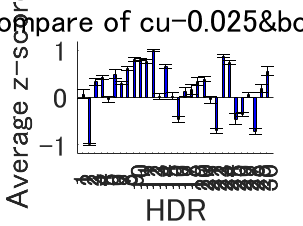

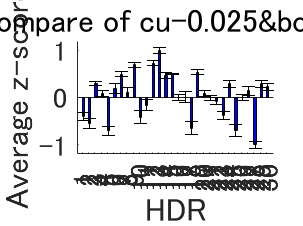

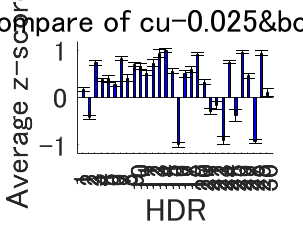

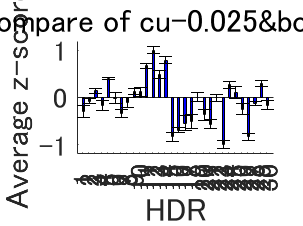

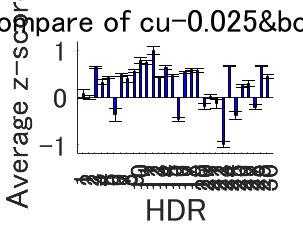

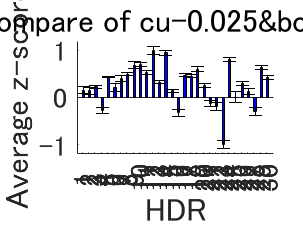

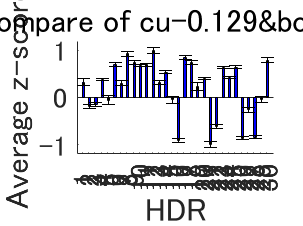

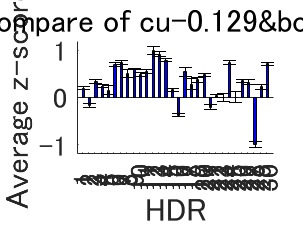

%-----------------------------------
% Exp3 Material Shape
%-----------------------------------
for matnum = 1:size(Exp3RowMHS,1)
    for shapenum = 1:size(Exp3RowMHS,3)
        figure;
        hold on;
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, Exp3MHSNorm(matnum, :, shapenum), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        errorbar(x + bar_width/2, Exp3MHSNorm(matnum, :, shapenum), error_Exp3MHS(matnum,:,shapenum), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' MatNames2{matnum} '&' ShapeNames{row}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    
        plotname = strcat(ana_result, '/O_MS_', MatNames2{matnum},ShapeNames{row},'.jpg');
        saveas(gcf, plotname);
        hold off;
    end
end

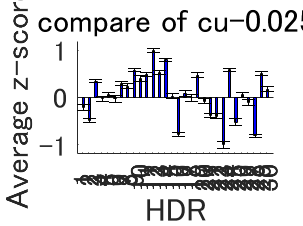

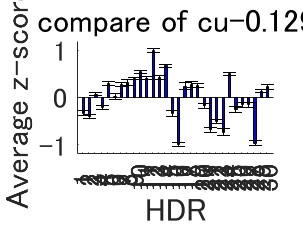

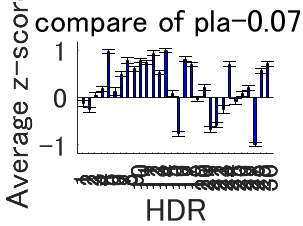

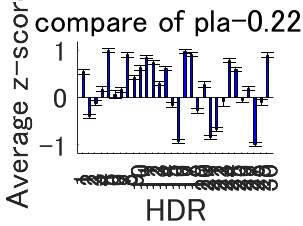

%-----------------------------------
% Exp3 Material
%-----------------------------------
%bar graph
for row = 1:4
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3MHNorm(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3MHNorm(row, :), error_Exp3MH(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' MatNames2{row}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');

    plotname = strcat(ana_result, '/O_M_', MatNames2{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

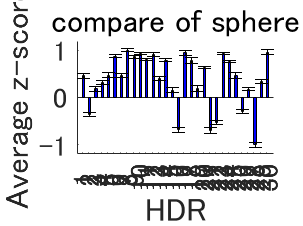

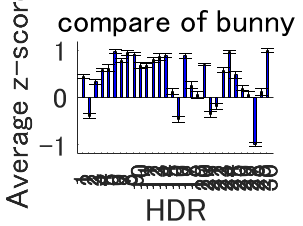

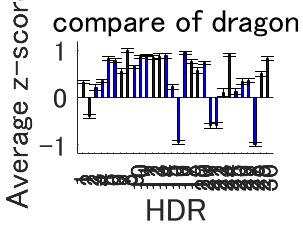

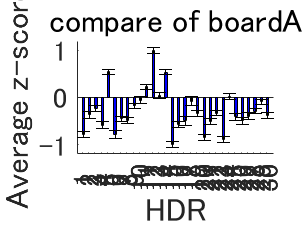

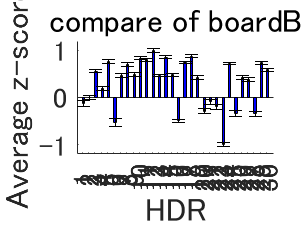

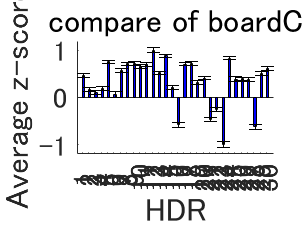

%-----------------------------------
% Exp3 Shape
%-----------------------------------
for row = 1:size(Exp3RowSH,1)
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3SHNorm(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3SHNorm(row, :), error_Exp3SH(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' ShapeNames{row}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');

    plotname = strcat(ana_result, '/O_S_', ShapeNames{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

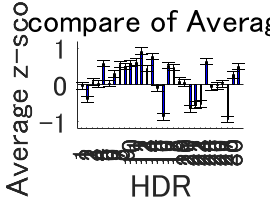

%-----------------------------------
% Exp3 All Average
%-----------------------------------
AvExp3zscore = mean(Exp3MHSNorm, 1);
Exp3Matrix = [Exp3MHSNorm;AvExp3zscore];
error_av_O = std(AvExp3zscore, 0, 2)/ sqrt(size(AvExp3zscore, 2));
error_av_O = repmat(error_av_O, 1, 30);

figure;
hold on;
bar_width = 0.35;
x = 1:length(HDRNames);
avb = bar(x + bar_width/2, AvExp3zscore, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh = errorbar(x + bar_width/2, AvExp3zscore, error_av_O, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(HDRNames3));
set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Average z-score', 'FontSize', 16);
title('compare of Average', 'FontSize', 16);
plotname = strcat(ana_result, '/O_Average.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue Load
%-----------------------------------
load('./inouedata/reshaped/z_psvList.mat')

load('./inouedata/reshaped/z_conditionList_2.mat')
condition_exp2 = experiment_condition;

%-----------------------------------
% Material
%-----------------------------------
searchColumn = [1,3];

groupColumns = condition_exp2(:, searchColumn);

columnCells = num2cell(groupColumns, 1);
[MatgroupIdx, uniqueGroups1,uniqueGroups2] = findgroups(columnCells{:});

groupMeans = splitapply(@(x) mean(x, 1), psv_experiment2, MatgroupIdx);

%正規化
InoueMHNorm = zeros(size(groupMeans));
for i = 1:size(groupMeans,1)
    row_min = min(groupMeans(i, :));
    row_max = max(groupMeans(i, :));
    
    InoueMHNorm(i, :) = 2 * (groupMeans(i, :) - row_min) / (row_max - row_min)-1;
end

InoueMatname = strcat(uniqueGroups1,'-', uniqueGroups2);
%-----------------------------------
% Shape
%-----------------------------------
searchColumn = 2;

groupColumns = condition_exp2(:, searchColumn);

columnCells = num2cell(groupColumns, 1);
[ShapegroupIdx, uniqueGroups1] = findgroups(columnCells{:});

groupMeans = splitapply(@(x) mean(x, 1), psv_experiment2, ShapegroupIdx);

%正規化
InoueSHNorm = zeros(size(groupMeans));
for i = 1:size(groupMeans,1)
    row_min = min(groupMeans(i, :));
    row_max = max(groupMeans(i, :));
    
    InoueSHNorm(i, :) = 2 * (groupMeans(i, :) - row_min) / (row_max - row_min)-1;
end

InoueShapeName = uniqueGroups1;
%-----------------------------------
% Material & Shape
%-----------------------------------
InoueRowMHS = zeros(4,30,6);

for i = 1:size(psv_experiment2,1)
    MatIdx = MatgroupIdx(i);
    ShapeIdx = ShapegroupIdx(i);
    InoueRowMHS(MatIdx,:,ShapeIdx) = psv_experiment2(i,:);
end
%正規化
InoueMHSNorm = zeros(size(InoueRowMHS));
for i = 1:size(InoueRowMHS,1)
    for j = 1:size(InoueRowMHS,3)
        row_min = min(InoueRowMHS(i, :, j));
        row_max = max(InoueRowMHS(i, :, j));
        
        InoueMHSNorm(i, :, j) = 2 * (InoueRowMHS(i, :, j) - row_min) / (row_max - row_min)-1;
    end
end

%-----------------------------------
% Average
%-----------------------------------
%Ave Data
AvgroupsMeans = mean(groupMeans, 1);
Av_Noromalized = zeros(size(AvgroupsMeans));
for i = 1:size(AvgroupsMeans,1)
    row_min = min(AvgroupsMeans(i, :));
    row_max = max(AvgroupsMeans(i, :));
    
    Av_Noromalized(i, :) = 2 * (AvgroupsMeans(i, :) - row_min) / (row_max - row_min)-1;
end

%-----------------------------------
% Inoue material
%-----------------------------------
for row = 1:size(InoueMHNorm,1)
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueMHNorm(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueMHNorm(row, :), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' InoueMatname{row}], 'FontSize', 16);

    plotname = strcat(ana_result, '/I_M_', InoueMatname{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

%-----------------------------------
% Inoue Shape
%-----------------------------------
for row = 1:size(InoueSHNorm,1)
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueSHNorm(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueSHNorm(row, :), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' InoueShapeName{row}], 'FontSize', 16);

    plotname = strcat(ana_result, '/I_S_', InoueShapeName{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

%-----------------------------------
% Inoue material shape
%-----------------------------------
for matnum = 1:size(InoueMHSNorm,1)
    for shapenum = 1:size(InoueMHSNorm,3)
        figure;
        hold on;
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, InoueMHSNorm(matnum, :, shapenum), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        %errorbar(x + bar_width/2, InoueMHSNorm(matnum, :, shapenum), error_Exp3MHS(matnum,:,shapenum), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' InoueMatname{matnum} '&' InoueShapeName{row}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    
        plotname = strcat(ana_result, '/I_MS_', InoueMatname{matnum},InoueShapeName{row},'.jpg');
        saveas(gcf, plotname);
        hold off;
    end
end


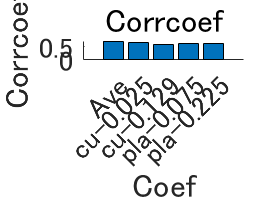

%-----------------------------------
% Exp3 vs Inoue Coef
%-----------------------------------
corrColumn = {'Ave','cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
corrVector = zeros(size(AvExp3zscore, 1)+1, 1);

correlation = corrcoef(AvExp3zscore, Av_Noromalized);
corrVector(1) = correlation(1, 2);
for i = 1:4
    correlation = corrcoef(Exp3MHSNorm(i, :), InoueMHNorm(i, :));
    corrVector(i+1) = correlation(1, 2);
end

figure;
hold on;
bar(corrVector);
set(gca, 'XTick', 1:length(corrColumn));
set(gca, 'XTickLabel', corrColumn, 'FontSize', 14);
xlabel('Coef', 'FontSize', 16); 
ylabel('Corrcoef', 'FontSize', 16);
title('Corrcoef', 'FontSize', 16);
plotname = strcat(ana_result, '/A_Coef_1.jpg');
saveas(gcf, plotname);
hold off;

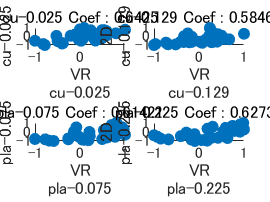


figure;
hold on;
for i = 1:4
    subplot(2, 2, i);
    scatter(Exp3MHSNorm(i, :), InoueMHNorm(i, :), 'filled');
    xlabel(['VR', MatNames2(i)]);
    ylabel(['2D', MatNames2(i)]);
    title(string(MatNames2(i)) + ' Coef : ' + string(corrVector(i+1)));
end
plotname = strcat(ana_result, '/A_Coef_2.jpg');
saveas(gcf, plotname);
hold off;

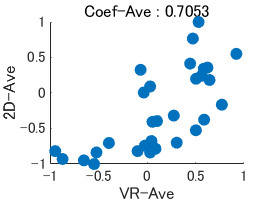


figure;
hold on;
scatter(AvExp3zscore, Av_Noromalized, 'filled');
xlabel('VR-Ave');
ylabel('2D-Ave');
title('Coef-Ave : ' + string(corrVector(1)));
plotname = strcat(ana_result, '/A_Coef_3.jpg');
saveas(gcf, plotname);
hold off;

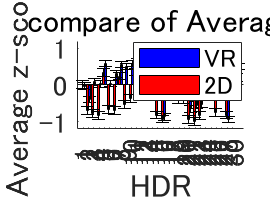

%-----------------------------------
% Exp3 vs Inoue graph
%-----------------------------------
figure;
hold on;
bar_width = 0.35;
x = 1:length(HDRNames);
avb1 = bar(x + bar_width/2, AvExp3zscore, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh1 = errorbar(x + bar_width/2, AvExp3zscore, error_av_O, 'k', 'linestyle', 'none');
avb2 = bar(x - bar_width/2, Av_Noromalized, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
avh2 = errorbar(x - bar_width/2, Av_Noromalized, error_av_I, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(HDRNames3));
set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Average z-score', 'FontSize', 16);
title('compare of Average', 'FontSize', 16);
legend([avb1, avb2], {'VR', '2D'}, 'Location', 'best');
plotname = strcat(ana_result, '/O_Average_hikaku.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp2 load
%-----------------------------------
resultmitsuba = "resultmitsuba/";
exp2path = "../Exp2/";

Exp2RowMHP = zeros(4, 15, 6);
exp2_subjects = {};

%allfileload
dirInfo = dir(exp2path + resultmitsuba);
exp2filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

%name
for foldernum =1:numFiles
    words = split(exp2filesNames{foldernum},{'_', '.'});
    if ~any(strcmp(exp2_subjects,words{1}))
        exp2_subjects{end + 1} = words{1};
    end
end

for foldernum =1:numFiles
    filename = fullfile(exp2path + resultmitsuba, exp2filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(MatNames1)
        sheetName = MatNames1{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};

        words = split(exp2filesNames{foldernum},{'_', '.'});

        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            HDRIndex = find(HDRlNames2 == idNum);
            MatIndex = find(strcmp(MatNames1, sheetName));
            ParticipantsIndex = find(strcmp(exp2_subjects,words{1}));
            if ~isempty(HDRIndex) && ~isempty(MatIndex) && ~isempty(ParticipantsIndex)
                Exp2RowMHP(MatIndex, HDRIndex,ParticipantsIndex) = Exp2RowMHP(MatIndex, HDRIndex,ParticipantsIndex) + scores(i)/5;
            end
        end
    end
end

..\Exp2\resultmitsuba\kawahara_mitsuba_exp2.xlsx
..\Exp2\resultmitsuba\killian_mitsuba_exp2.xlsx
..\Exp2\resultmitsuba\kyou_mitsuba_exp2.xlsx
..\Exp2\resultmitsuba\miyoshi_mitsuba_exp2.xlsx
..\Exp2\resultmitsuba\okamoto_mitsuba_exp2.xlsx
..\Exp2\resultmitsuba\satou_mitsuba_exp2.xlsx


%-----------------------------------
% (Material,HDR)
%-----------------------------------
Exp2RowMH = mean(Exp2RowMHP,3);
%z-score
Exp2MHZs = zeros(size(Exp2RowMH));
for i = 1:size(Exp2RowMH, 1)
    Exp2MHZs(i, :) = zscore(Exp2RowMH(i, :));
end
%正規化
Exp2MHNorm = zeros(size(Exp2RowMH));
for i = 1:size(Exp2RowMH, 1)
    row_min = min(Exp2MHZs(i, :));
    row_max = max(Exp2MHZs(i, :));
    
    Exp2MHNorm(i, :) = 2 * (Exp2MHZs(i, :) - row_min) / (row_max - row_min)-1;
end
%標準誤差
error_Exp2MH = std(Exp2RowMHP, 0, 3)/ sqrt(size(Exp2RowMHP,3));
error_Exp2MH_Norm = zeros(size(error_Exp2MH));
for i = 1:size(Exp2RowMH, 1)
    row_min = min(Exp2RowMH(i, :));
    row_max = max(Exp2RowMH(i, :));

    error_Exp2MH_Norm(i,:) = error_Exp2MH(i,:) / (row_max - row_min);
end

Exp2MHNorm30 = zeros(4, 30);
[isMember, colIdx] = ismember(HDRlNames2, HDRNames);
Exp2MHNorm30(:, colIdx(isMember)) = Exp2MHNorm;
error_Exp2MH30(:,colIdx(isMember)) = error_Exp2MH_Norm;

%-----------------------------------
% exp2 VS VR
%-----------------------------------
%bar graph
for row = 1:4
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(HDRNames);

    % exp2のプロット
    b2 = bar(x - bar_width/2, Exp2MHNorm30(row, :), bar_width, 'FaceColor', 'r', 'DisplayName', '2D'); 
    h2 = errorbar(x - bar_width/2, Exp2MHNorm30(row, :), error_Exp2MH(row,:), 'k', 'linestyle', 'none');

    % exp3のプロット
    b3 = bar(x + bar_width/2, Exp3MHSNorm(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    h3 = errorbar(x + bar_width/2, Exp3MHSNorm(row, :), error_Exp3MHS(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames));
    set(gca, 'XTickLabel', HDRNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' MatNames2{row}], 'FontSize', 16);
    legend([b2,b3],{'2D','3D'}, 'Location', 'best');

    plotname = strcat(ana_result, '/', MatNames2{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

%correlation_coefficients
correlation_coefficients = zeros(1, 4);
for row = 1:4
    data_exp2 = Exp2MHNorm30(row, :);
    data_exp3 = Exp3MHSNorm(row, :);
    corr_matrix = corrcoef(data_exp2, data_exp3);
    correlation_coefficients(row) = corr_matrix(1, 2);
end

disp(correlation_coefficients);
%}

%-----------------------------------
% Exp1
%-----------------------------------
resultmitsuba = "resultmitsuba/";
exp1path = "../Exp1/";

Exp1mitsubaMatrix = zeros(4, 15);
%allfileload
dirInfo = dir(exp1path + resultmitsuba);
exp2filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

for foldernum =1:numFiles
    filename = fullfile(exp1path + resultmitsuba, exp2filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(MatNames)
        sheetName = MatNames{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};
        
        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(HDRNames == idNum);
            rowIndex = find(strcmp(MatNames, sheetName));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                Exp1mitsubaMatrix(rowIndex, colIndex) = Exp1mitsubaMatrix(rowIndex, colIndex) + scores(i);
            end
        end
    end
end
Exp1mitsubaMatrix = Exp1mitsubaMatrix ./ numFiles;

error_exp1 = std(Exp1mitsubaMatrix, 0, 2)/ sqrt(size(Exp1mitsubaMatrix, 2));
error_exp1 = repmat(error_exp1, 1, 15);